# Getting Started with the ELARA Toolbox

**Welcome to the ELARA toolbox!**

This live script gives a short introduction to the main ELARA workflow for simulating the dynamics of rigid-flexible systems.

## Installation

A successful installation can be checked with

elara.setup;

Verifying ELARA toolbox installation...
  [PASS]  Core toolbox installed correctly.
  [PASS]  Compiled MEX files found under elara.mex.
  [PASS]  CasADi installation found.


To improve simulation performance, MATLAB Coder can be used to build MEX files for important functions. An appropriate compiler is configured with

% mex -setup C++

The MEX files can then be built using

% elara.build;

After the MEX files are compiled successfully, they will be automatically used by the toolbox.

For optimal control, CasADi is required. It is available from the [CasADi website](https://web.casadi.org/) and needs to be added to the MATLAB path.

## **Defining a System**

The first step is defining the system to be simulated. For this, ELARA provides two classes to specify the different link types:

- `elara.RigidLink` to define a rigid body

- `elara.FlexibleLink` to define a flexible link, which is modeled as a geometrically exact (Cosserat) beam and can undergo large rotations and deformations.

Each link is connected to a parent link (or the fixed base) via a one-DOF screw joint, e.g., a revolute or a finite-pitch screw joint. The parent indices may define an open kinematic tree. Moreover, it is possible to specify cantilever beams, which are directly fixed to the base without any moving joint. This is the case for the system used here.

Both classes are child classes of `elara.abstract.Link`, and can be directly assembled together into a heterogeneous array.

Several example systems are already included. Here, a flexible cantilever link with two rigid bodies attached through revolute joints is used:

% Make the supplied example system definitions available
addpath(fullfile(elara.internal.getToolboxRootFolder, ...
    "examples", "example-systems"));

links = systemDef_cantilever_system();

The function directly returns a link array, where each element is one of the two link types described above.

## Setting up the Simulation

A `elara.Simulation` object is generated by passing the specified links to the constructor:

simulation = elara.Simulation(links, "displayInfo",false)

simulation =   Simulation with properties:

          Name: ""
    integrator: [1×1 elara.integration.VIBroyden]
         links: [3×1 elara.abstract.Link]
        system: [1×1 elara.SystemNum]
    parameters: [1×1 elara.SimulationParameters]
       results: [1×1 elara.SimulationResults]


In this step, the individual links are assembled into a complete multibody system, which contains all information and properties required for simulations or optimal control applications.

This multibody system is stored in the `system` property of the `simulation` object:

system = simulation.system

system =   SystemNum with properties:

                  frames: [1×1 elara.FramePropertiesNum]
                    cSys: [17×1 double]
                    dSys: [17×1 double]
                    qRef: [17×1 double]
            isCantilever: 1
                      g0: [4×4 double]
     LinkAdjacencyMatrix: [3×3 double]
    FrameAdjacencyMatrix: [7×7 double]
                  nLinks: 3
                 nJoints: 2
                 nFrames: 7
                    nDoF: 17
                 nInputs: 2
        linkFrameIndices: [2×3 uint16]
           indexTCPFrame: 0
                 g_B_TCP: [4×4 double]


Various properties can be adjusted after the system has been created. For this example, the simulation name and the orientation of the first link are changed by specifying an appropriate SE(3) transformation matrix:

% Construct rotation matrix
RRef0 = [
    0  0 1
    0  1 0
    -1 0 0
    ];

% Set pose of the first link via homogeneous transformation matrix (optional)
simulation.system.g0 = elara.SE3.matrix(RRef0, zeros(3,1));

% Name of the simulation (optional; it is used, for example, in figure names)
simulation.Name = "My first simulation";

The system can now be displayed using the built-in visualization methods:

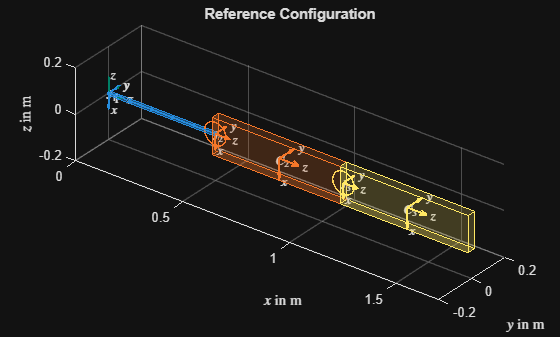

% Visualization of the system in its reference configuration
% (i.e., for q = 0)
simulation.visualizeSystemRefConf;
xlim([0,1.7]);
ylim([-0.2,0.2]);
zlim([-0.2,0.2]);

## Specifying Simulation Parameters

Before the simulation is started, its duration, initial configuration, initial velocity, and any inputs are supplied through the `simulation.parameters` property.

% End time
simulation.parameters.tEnd = 5;

The initial configuration is specified via the initial values of the system's generalized coordinates. For the present system, these are the discrete deformations of the beam segments, and the two joint angles of the revolute joints.

The initial configuration can simply be initialized as zero, so that the simulation starts in the system's reference configuration:

simulation.parameters.q0 = zeros(simulation.system.nDoF, 1);

Nonzero initial configurations can also be specified. For example, the joint angles can be set to selected values:

q0 = simulation.system.setJointAngles(deg2rad([-30,90]));
simulation.parameters.q0 = q0;

The initial velocity is specified analogously. Here, the system is started from rest:

simulation.parameters.qDot0 = zeros(simulation.system.nDoF,1);

The selected initial configuration can be displayed before the simulation is run:

simulation.visualizeSystemConfig(simulation.parameters.q0);
xlim([0,1.5]);
ylim([-0.2,0.2]);
zlim([-0.3,0.6]);
title("Initial Configuration");

## Setting up the Integrator

Next, the integration method used for the simulation is selected. The type and parameters of the integrator can be set using the `simulation.integrator` property.

Here, the Lie-group variational integrator (LGVI) is used. It advances the configurations directly on SE(3) and is particularly well suited to many systems containing flexible links.

simulation.integrator = elara.integration.VIBroyden;

Its main accuracy and stability parameter is the integration time step $h$:

simulation.integrator.h = 2^-10;

A first-order dissipation term is selected here for increased computational efficiency:

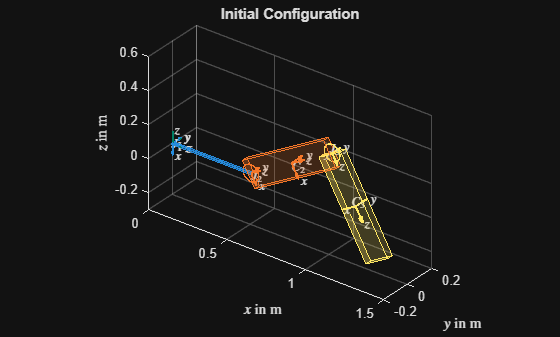

simulation.integrator.useFirstOrderDissipation = true;

Several additional LGVI parameters are available for fine-tuning performance and robustness. They are left at their default values in this introductory example.

## Running the Simulation

Once all parameters have been set, the simulation is started. By default, the solver displays some metadata and statistics:

simulation = simulation.simulateSystem;

The raw numerical results of the simulation are then available as an `elara.SimulationResults` object at:

simulation.results

## Post-Processing and Plotting

After the simulation has finished, the built-in plotting and visualization tools can be used to inspect the results.

## Generating Plots

A selection of useful plots is generated with:

% Snapshots of the simulation results
simulation.drawSnapshots("nSnapShots", 10);
% Joint angles over time
simulation.plotJointAngles;
% Configurations, velocities, and discrete deformations of the cantilever beam
simulation.plotBeamData;
% Absolute positions of certain system frames (including the cross-section

Starting integration (varint-broyden)...
   Total integration time (tictoc):     0.267999 s
   Simulation end time:                 5.000 s
   Number of successful time steps:     5121
   Time step:                           9.766e-04 s = 2^-10.00 s
   Approx. comp. time per step:         5.233e-05 s
   Iteration Count (Avg/Min/Max/Total): 3.1436 / 2 / 6 / 16095
   Residual (Avg/Min/Max):              2.931e-09 / 7.927e-13 / 9.981e-09
   Target solver error violations:      0 (0.00% of overall steps)


% frames of the cantilever beam and the reference frames of the rigid
% bodies)
simulation.plotFramePositions;

ans =   SimulationResults with properties:

                 eta: [6×7×5121 double]
                   g: [4×4×7×5121 double]
                   q: [17×5121 double]
               q_dot: [17×5121 double]
                tout: [5121×1 double]
       kineticEnergy: [0×1 double]
     potentialEnergy: [0×1 double]
        strainEnergy: [0×1 double]
         totalEnergy: [0×1 double]
    solverIterations: [2 2 2 3 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 3 2 2 2 2 2 2 2 2 3 2 2 2 3 2 2 3 2 2 3 2 3 2 3 2 3 2 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 4 4 4 4 4 … ] (1×5121 double)
      solverResidual: [5.3697e-09 7.4937e-09 1.4713e-09 1.4571e-11 4.4302e-09 1.0926e-09 2.5384e-09 1.0478e-10 2.1953e-10 8.2432e-10 1.1525e-09 2.6655e-09 3.0784e-09 3.9154e-09 3.9137e-09 5.1657e-09 5.7480e-09 7.4193e-09 8.3410e-09 … ] (1×5121 double)
      solverExitFlag: [0 0 0

% All available plots can also be generated at once with
% simulation.plotAll;

## Animating the Simulation Results

Finally, the completed simulation can be animated with:

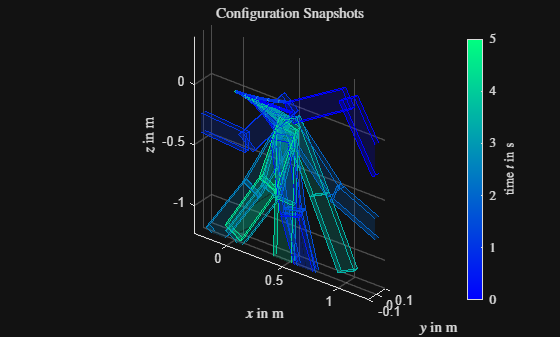

simulation.animateSimResults("figureName", "Animation Getting Started Guide");

## Detailed Example Scripts

Further capabilities are demonstrated by the scripts included in the `examples` folder. These can be run directly or used as templates.

For dynamical simulation, the included examples are:

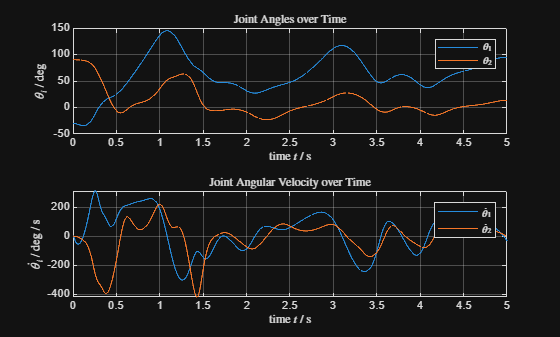

% simulation_continuum_manipulator
% simulation_rigid_flexible_system

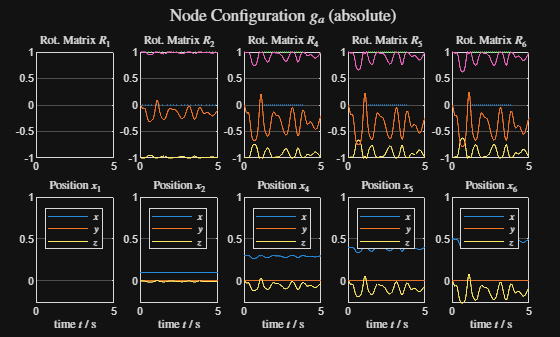

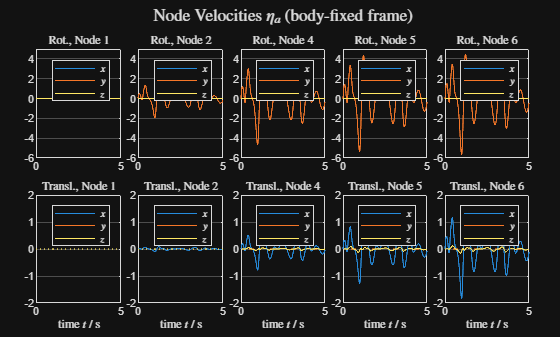

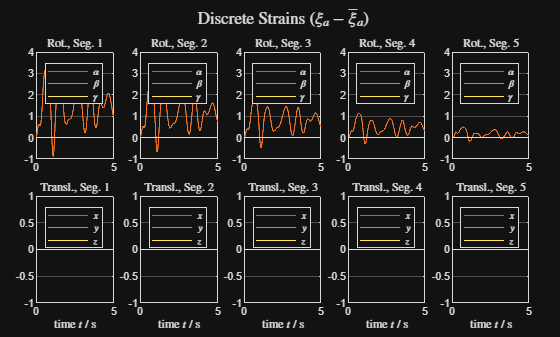

% simulation_rigid_robot
% simulation_rigid_flexible_robot_PD_control

% simulation_chiemsee_lecture_notes

Together, these examples demonstrate both the Lie-group variational integrator and the standard ODE-solver workflows.

## Optimal Control Examples

Additionally, there are several examples that demonstrate the use of ELARA for optimal control applications. To run these examples, CasADi is required.

The implemented examples are:

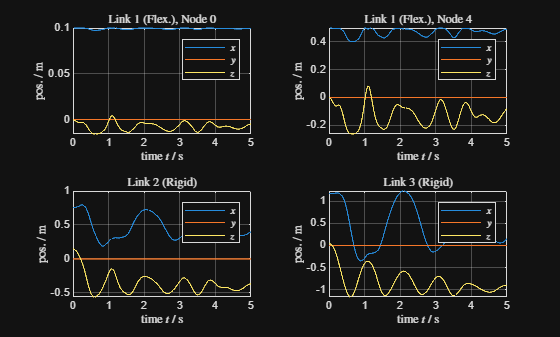

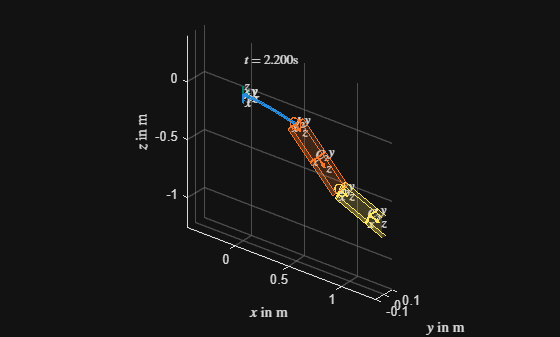

% optimal_control_planar_robot
% optimal_control_rigid_robot
% optimal_control_continuum_manipulator